# Segment Analyze

做segment对齐和标记

后面还要修改split的逻辑，根据标记来处理数据集

1. event/total

2. 计算delay（要不要先把中间空白的那一段剪掉？）（先不减，用全部算一次，再用不要前面一部分算一次，看看有没有很大区别owo？）

3. 计算response time

4. 标记需要训练的数据段，向前留出足够的history

5. check一下数据集长度

close all;clear;clc;
[M1, mPFC, ratios, eventTrain, M1num, mPFCnum, actTrain] = spikeTime2Train("data/data_rat010_0615_event.mat");
fprintf(['M1withSpike=%0.4f\nmPFCwithSpike=%0.4f\nM1multiSpike=%0.4f\n' ...
  'mPFCmultiSpike=%0.4f'], ratios)

M1withSpike=0.2069
mPFCwithSpike=0.1322
M1multiSpike=0.1154
mPFCmultiSpike=0.0669

sum(eventTrain)

ans = 42192

successCount = 0;
spikeLength = length(eventTrain);
for i=2:spikeLength
  if (eventTrain(i-1) == 1 && eventTrain(i) == 0)
    successCount = successCount + 1;
  end
end
successCount

successCount = 164

responseTime = zeros(1,successCount);
trailNum = 1;
for i=2:spikeLength
  if (eventTrain(i-1) == 1 && eventTrain(i) == 0)
    trailNum = trailNum + 1;
  end
  if (eventTrain(i) == 1)
    responseTime(trailNum) = responseTime(trailNum) + 1;
  end
end
responseTime = responseTime/100;

response time大于6s的不要了

trailTooLong = find(responseTime>6);
eventTrainRow = eventTrain;
trailNum = 0;
for i=2:spikeLength
  if (eventTrainRow(i-1) == 0 && eventTrainRow(i) == 1)
    trailNum = trailNum + 1;
  end
  if (eventTrainRow(i) == 1 && ismember(trailNum, trailTooLong))
    eventTrain(i) = 0;
  end
end

sum(eventTrain)

ans = 37234

successCountRow = successCount;
successCount = 0;
for i=2:spikeLength
  if (eventTrain(i-1) == 1 && eventTrain(i) == 0)
    successCount = successCount + 1;
  end
end
successCount

successCount = 157

responseTimeRow = responseTime;
responseTime = zeros(1,successCount);
trailNum = 1;
for i=2:spikeLength
  if (eventTrain(i-1) == 1 && eventTrain(i) == 0)
    trailNum = trailNum + 1;
  end
  if (eventTrain(i) == 1)
    responseTime(trailNum) = responseTime(trailNum) + 1;
  end
end
responseTime = responseTime/100;

Plot

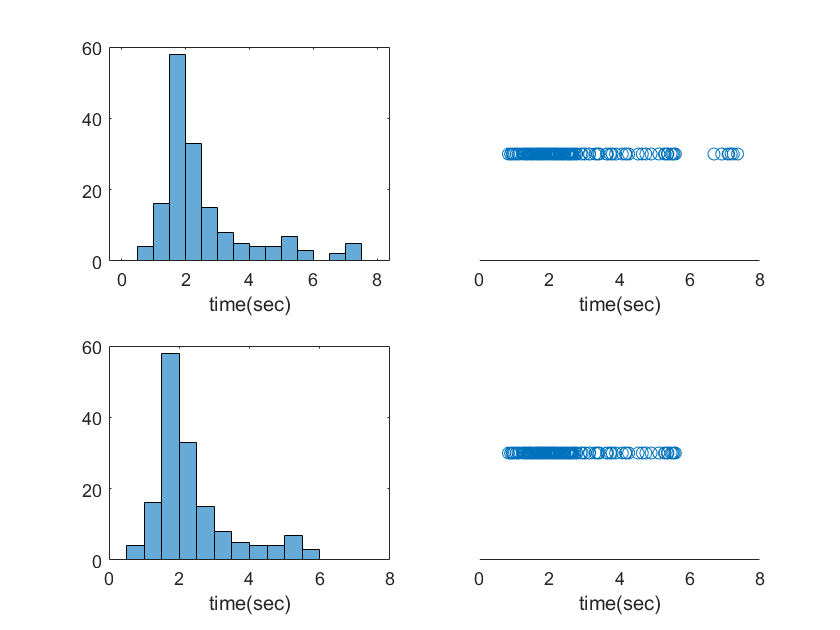

figure
subplot(2,2,1)
histogram(responseTimeRow, [0 0.5 1 1.5 2 2.5 3 3.5 4 4.5 5 5.5 6 6.5 7 7.5 8])
xlabel("time(sec)")
subplot(2,2,3)
histogram(responseTime)
xlabel("time(sec)")
xlim([0,8])
subplot(2,2,2)
scatter(responseTimeRow,zeros(1,successCountRow))
xlabel("time(sec)")
set(gca, 'TickLength', [0 0])
set(gca, 'ytick', [])
set(gca, 'box', 'off')
set(gca,'YColor','white')
subplot(2,2,4)
scatter(responseTime,zeros(1,successCount))
xlabel("time(sec)")
xlim([0,8])
set(gca, 'TickLength', [0 0])
set(gca, 'ytick', [])
set(gca, 'box', 'off')
set(gca,'YColor','white')

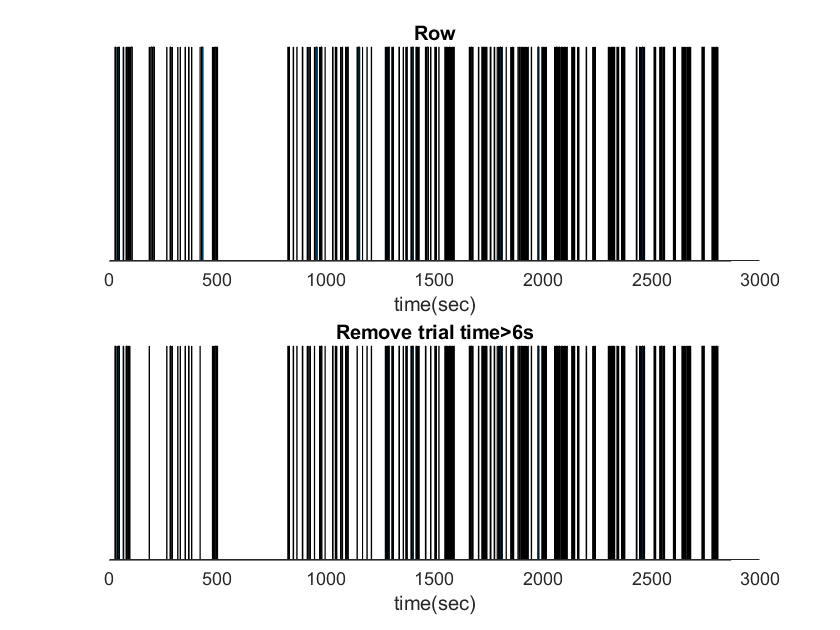

figure
subplot(2,1,1)
spikeLengthRow = length(eventTrainRow);
area(0.01:0.01:spikeLengthRow*0.01, eventTrainRow)
set(gca, 'TickLength', [0 0])
set(gca, 'ytick', [])
set(gca, 'box', 'off')
set(gca, 'YColor', 'white')
xlabel("time(sec)")
title('Row')
subplot(2,1,2)
spikeLength = length(eventTrain);
area(0.01:0.01:spikeLength*0.01, eventTrain)
set(gca, 'TickLength', [0 0])
set(gca, 'ytick', [])
set(gca, 'box', 'off')
set(gca, 'YColor', 'white')
xlabel("time(sec)")
title('Remove trial time>6s')

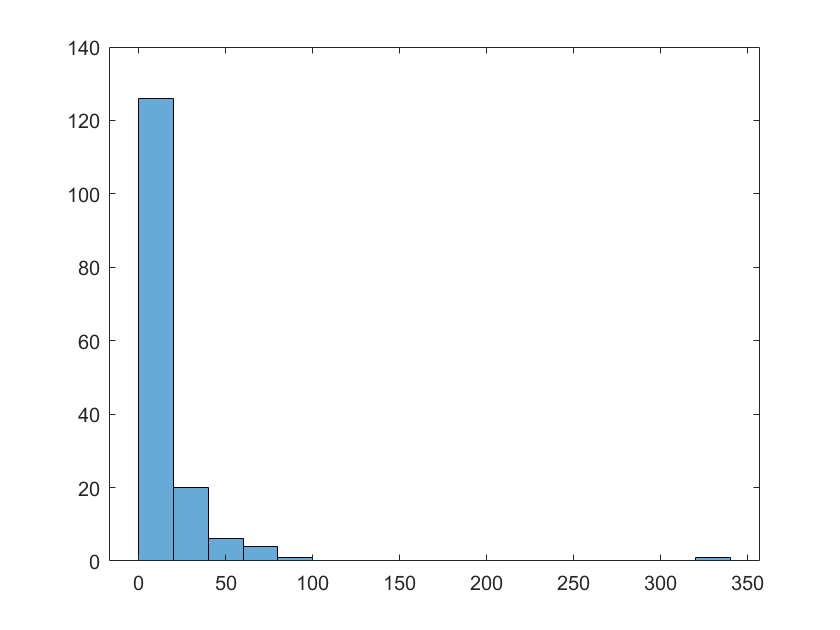

% 统计trail之间的事件，比较长的扔掉？或者直接只取trail前后一段比较长的事件，不管optimal delay了
emptyTime = zeros(1,successCount+1);
trailNum = 1;
emptyTime(1) = 1;
for i=2:spikeLength
  if (eventTrain(i)==0)
    emptyTime(trailNum) = emptyTime(trailNum)+1;
  end
  if (eventTrain(i-1) == 0 && eventTrain(i) == 1)
    trailNum = trailNum + 1;
  end
end
emptyTime = emptyTime/100;
figure
histogram(emptyTime)

计算delay，delay一个时间点，然后计算mutual information

takenBins = 82001:160000;
eventTrainPart = eventTrain(takenBins)';
actTrainPart = actTrain(takenBins)';
mPFCPart = mPFC(takenBins,:);
M1Part = M1(takenBins,:);

M1delayMI   = zeros(M1num, 71);
mPFCdelayMI = zeros(mPFCnum, 71);
for delay=0:70 % delay vary from 0ms~700ms
  M1delayMI(:,delay+1) = mutualInformation(M1Part(1:end-delay,:), actTrainPart(delay+1:end));
  mPFCdelayMI(:,delay+1) = mutualInformation(mPFCPart(1:end-delay,:), eventTrainPart(delay+1:end));
end

M1与actionTrain之间的delay在某几个neuron上很明显

actionTrain：把press和release动作前后50ms赋值为1，其余时间为0

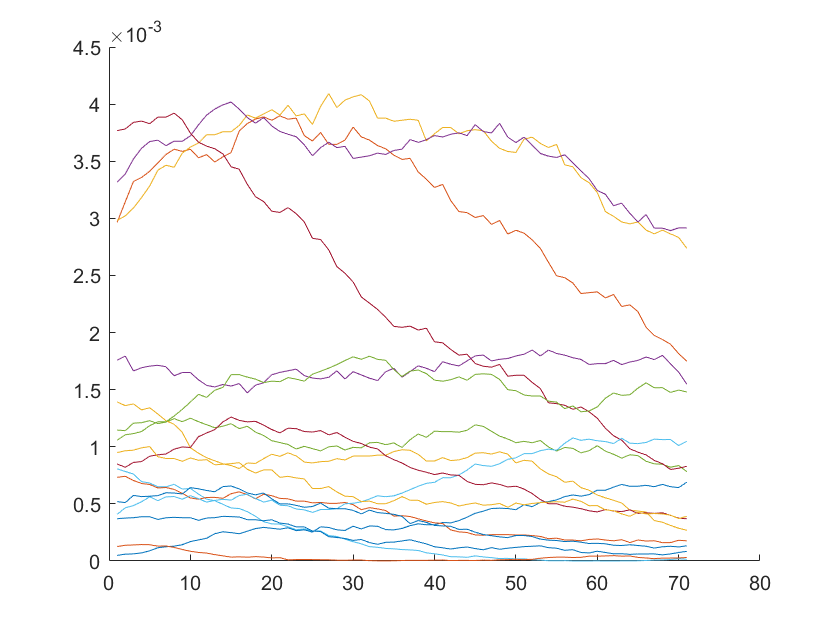

figure
hold on
for i=1:M1num
  plot(M1delayMI(i,:))
end
hold off

其中[2 3 4 7 11 17]相对高

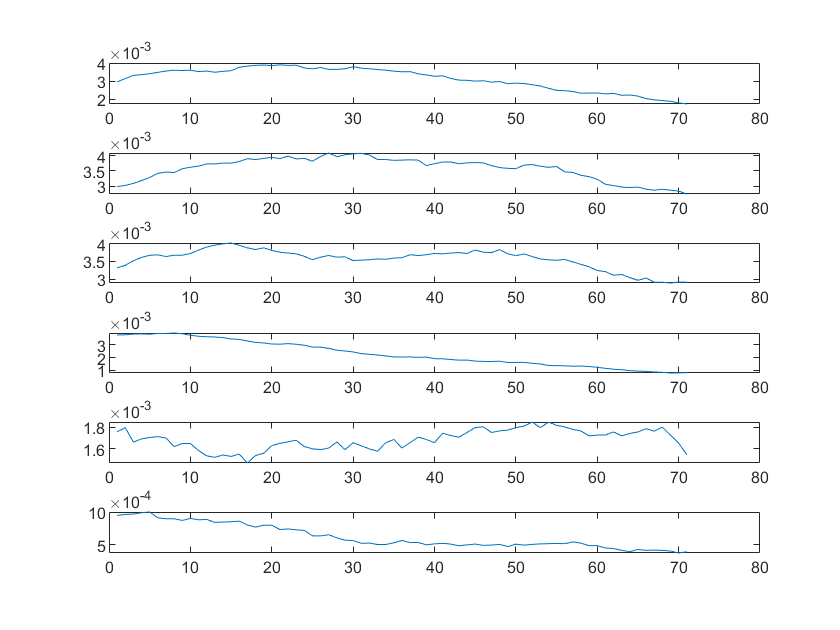

figure
hold on
for i=[2 3 4 7 11 17]
  subplot(6,1,find([2 3 4 7 11 17]==i))
  plot(M1delayMI(i,:))
end
hold off

mPFC和event之间似乎没有明显的delay关系

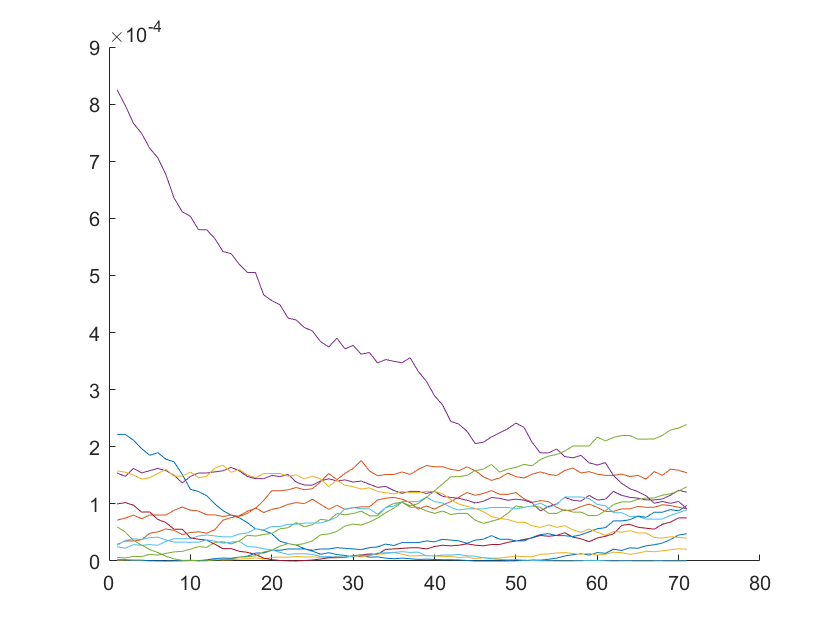

figure
hold on
for i=1:mPFCnum
  plot(mPFCdelayMI(i,:))
end
hold off

save some results

M1neurons   = [7 2 3];
mPFCneurons = [5 6 7 8 13];
M1spike = M1(:, M1neurons);
mPFCspike = mPFC(:, mPFCneurons);
optimalDelay = [find(M1delayMI(M1neurons(1),:)==max(M1delayMI(M1neurons(1),:))), find(M1delayMI(M1neurons(2),:)==max(M1delayMI(M1neurons(2),:))), find(M1delayMI(M1neurons(3),:)==max(M1delayMI(M1neurons(3),:)))]-1;
save("data/data_rat010_0615_spike_train_selected_with_delay.mat", "M1spike", "mPFCspike", "eventTrain", "optimalDelay")